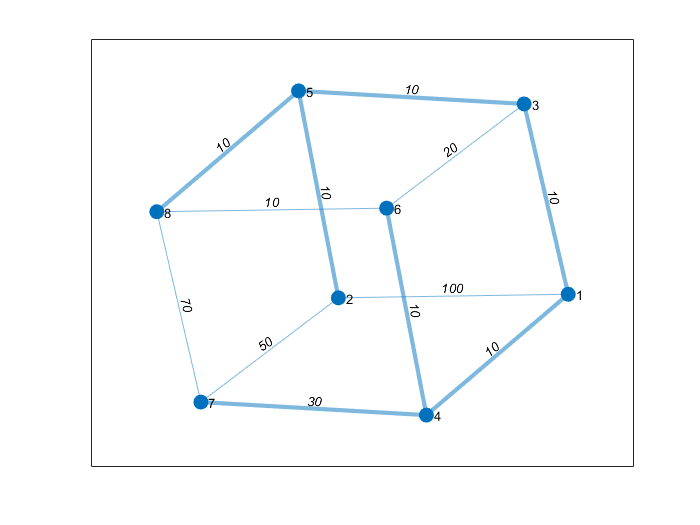

%博客案例一
s = [1 1 1 2 5 3 6 4 7 8 8 8];
t = [2 3 4 5 3 6 4 7 2 6 7 5];
weights = [100 10 10 10 10 20 10 30 50 10 70 10];
G = graph(s,t,weights);
p = plot(G,'EdgeLabel',G.Edges.Weight);
[T,pred] = minspantree(G);
highlight(p,T)

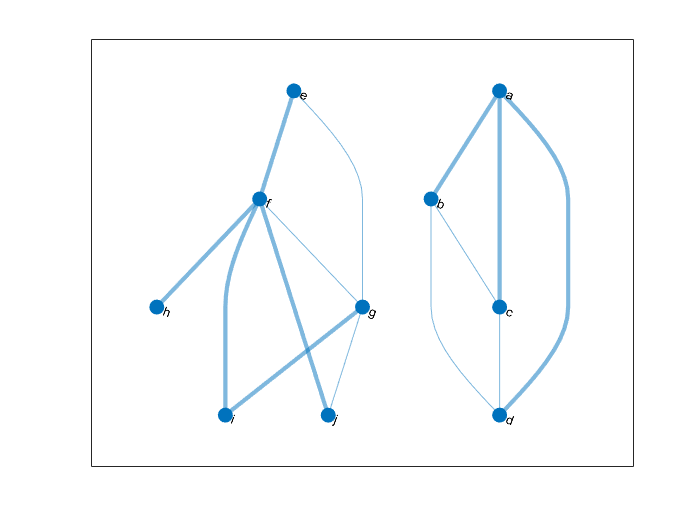

%博客案例二
s = {'a' 'a' 'a' 'b' 'b' 'c' 'e' 'e' 'f' 'f' 'f' 'f' 'g' 'g'};
t = {'b' 'c' 'd' 'c' 'd' 'd' 'f' 'g' 'g' 'h' 'i' 'j' 'i' 'j'};
G = graph(s,t);
p = plot(G,'Layout','layered');
[T,pred] = minspantree(G,'Type','forest','Root',findnode(G,'i'));
highlight(p,T)

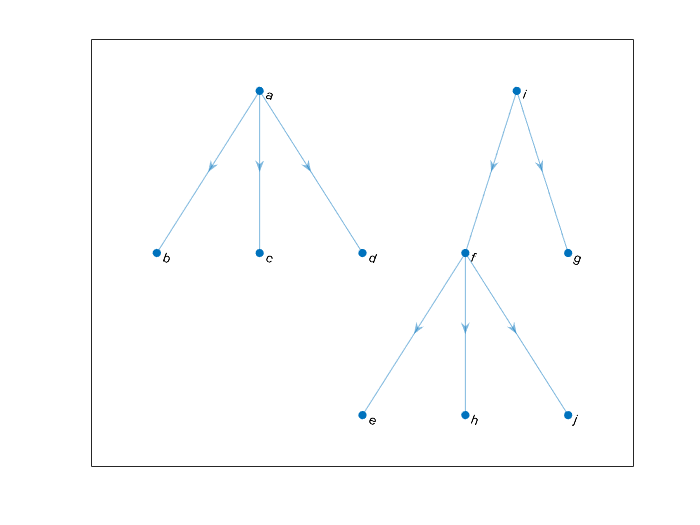

rootedTree = digraph(pred(pred~=0),find(pred~=0),[],G.Nodes.Name);
plot(rootedTree)